#                                                 Object Avoidance Using Dynamic Programming, 

#                                                         Full State Observer and Pole Placement.

                                                                                                                      by Benjamin Brandwin

## Problem Formulation

Object Avoidance by autonomous systems is of increasing importance in todays technology. With the advent of self-drving cars and Amazon's dream to deliver packages via self-driven autonomous UAV's, basic object avoidance and navigation by autonomous systems has a become a highly valuable research undertaking. 

In this paper we will explore multiple object avoidance using dynaimc programing to determine the shortest path through a maze of obstacles, and then design a full-state observer and controller using pole placement with error intergator and controller dynamics to follow a time dependant trajectory and navigate the maze autonomously.

We take our system dynamics to be that of a point mass subject to


$$\bf{F =M\ddot{x}}$$


with 


$$\bf{\ddot{x} = u_x}$$



$$\bf{\ddot{y} = u_y}$$



$$\bf{\dot{u} = -5u_c + 0.4u$$



$$\bf{\dot{X} = AX + Bu}$$



$$\bf{Y = CX + Du$$


where we have 


$$\bf{A} = \pmatrix{0&1&0&0&0&0&0 \cr 0&0&1&0&0&0&0 \cr 0&0&0&0&0&0&0 \cr 0&0&0&0&1&0&0\cr 0&0&0&0&0&1&0 \cr 0&0&0&0&0&0&0 \cr 0&0&0&0&0&0&-5}$$



$$\bf{B = \pmatrix{0&0 \cr 0&0\cr 1&0\cr 0&0\cr 0&0\cr 0&1\cr .4&.4 }$$



$$\bf{C = \pmatrix{1&0&0&0&0&0&0 \cr 0&1&0&0&0&0&0 \cr 0&0&0&1&0&0&0 \cr 0&0&0&0&1&0&0 \cr 0&0&0&0&0&0&1}$$



$$\bf{D=0}$$



$$\bf{X} = \pmatrix{e_x \cr x \cr \dot{x} \cr e_y \cr y \cr \dot{y} \cr u}$$



$$\bf{Y = \pmatrix{e_x \cr x \cr e_y \cr y \cr u}$$


## Part 1: Setup

In the first part we begin by constructing a 10x10 grid with discretizations at 0.1 along the X and Y axis, as well as obstacles. The Setup code initializes various parameters including the max and min values for x and y, the starting position and goal for the robot, as well as initializing  a matrix to represent obstacles and well as a matrix to represent the "distance-to-go" at each discretized point in the grid. This code also sets up a "buffer zone" around all of the obstacles to prevent our robot from coming too close to the walls of the maze. 

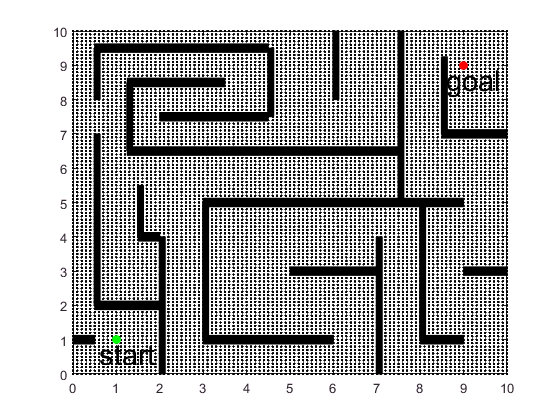

clc
close all 
clear all
Setup;

## Part 2 : Value Iteration Matrix (Dynamic Programming)

In the next section we apply dynamic programming to create our "cost-to-go" matrix which asigns values to each point in the maze according to the minimum number of steps required to go from that point to the goal. Pseudocode is as follows $^1$:

- Initialization

-     Set cost-to-go, J to a large value.

-     Discretize state-action pairs

-     Set cost-to-go as 0 for the goal.

-     Set point_to_check_array to contain goal.

- Repeat until no-values are updated,

-     For each element in the grid, take all the possible actions and compute the incurred costs.

-     For each action, compute the cost-to-go of the new state.

-     Update self if cost-to-go of the new state plus action is lower than current cost-to-go.

The resulting map creates a "ramp" of desending values in between the obstacles as we get closer to the goal. This value map can then be used to generate the shortest distance to the goal from any point in the maze. 

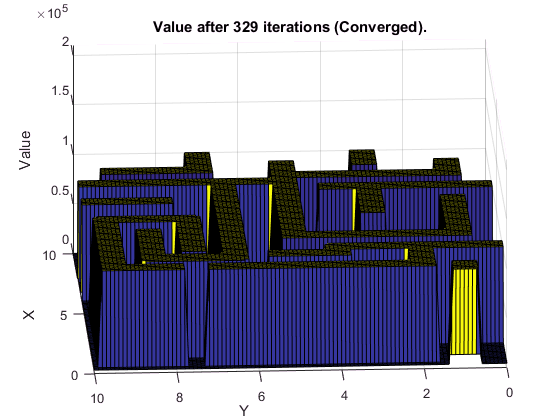

Generate_Surface;

## Part 3: Path Generation

In the next section we generate a path through the maze. Using the value map generated in part 2 we can start at any point in the map and at each step examine all neighbors. We then simply add the neighbor with the lowest value to our desired path. A gradient descent algorithm is then used to smooth the path and place points at equal distances along the curve. In doing so we ensure that the velocity of our point mass remains fairly constant as it turns around corners of the maze. The gradient descent algorithm is as follows:


$$\bf{\hat{XY}_i = \hat{XY}_i + \beta(XY_i - \hat{XY}_i) + \gamma(\hat{XY}_{i-1} - 2\hat{XY}_i + \hat{XY}_{i+1})$$


iterated from 2 to N-1 where N is the number of points in the curved path. The buffer zone created in our setup ensures that our curved path does not intersect any obstacles

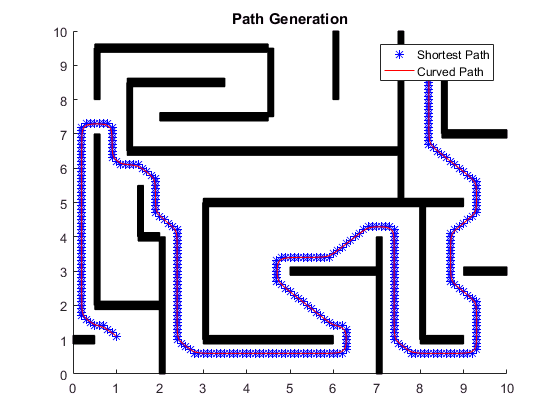

Generate_Path;
Curve_Path;

## Part 4 and 5: Observer and Controller Design

In the next section a full state observer is used along with a controller design using pole placement to track a time dependant setpoint. A full state observer was chosen as it has a slightly easier implemetation than other methods and should be sufficiently accurate for the purposes of this task. 

Our observer estimate is 


$$\bf{\hat{\dot{X}} = A\hat{X} + Bu + L(Y - \hat{Y})$$


where 


$$\bf{\hat{Y} = C\hat{X} + Du}$$


after some algebra we find that 


$$\bf{\dot{e} = (A - LC)e$$


we can use pole placement to produce an L that places the eigen values of $\bf{(A - LC)}$ at negative values, thus sending $\bf{e \longrightarrow 0}$ as $\bf{t \longrightarrow \infty}$. By placing the poles of our observer at larger negative values than our controller we converge the observer results much quicker than the actuator can respond, resulting in better control. 

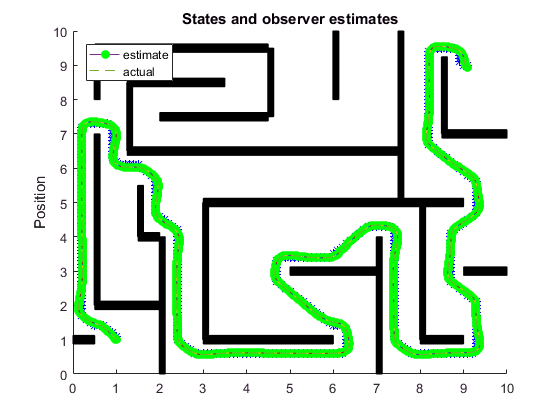

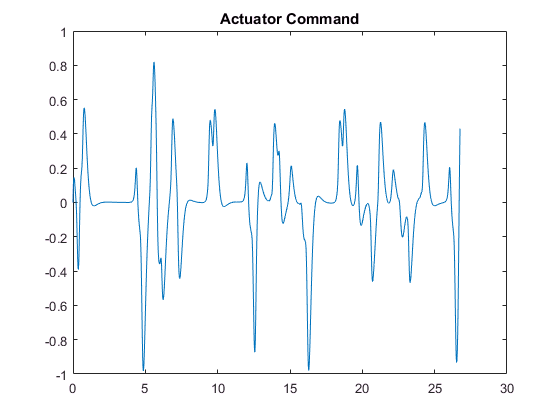

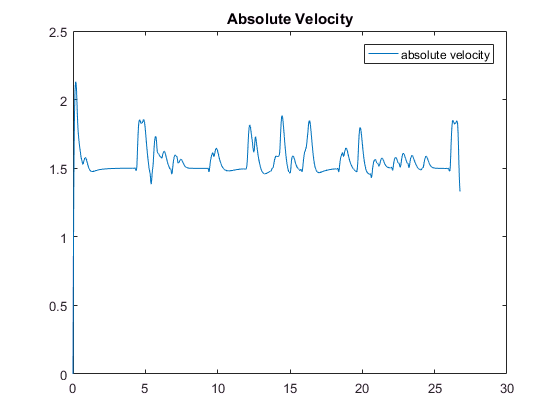

Observe_Control;

Above we can see that our full state observer and controller track the setpoint nicely and do not run into any walls. Our actuator dynamic was chosen (after some trial and error) to keep the maximum values of the actuator command between -1 and 1. However, we can see that our velocity jumps to over 2 initially and afterwards is extremely jagged. The required control signal is jagged as a result jumping up and down very quickly. 

One thing we can do to reduce the maximum velocity as well as smooth the curve is to add in friction. A frictional force will result in a terminal velocity for a given input, and should limit our system response. Our new dynamics equation then becomes


$$\bf{M\ddot{x} = F - b\dot{x}}$$


integrating we find 


$$\bf{\dot{x} = \frac{F}{b}(1 - e^{\frac{-bt}{M}}) + \dot{x}_0e^{\frac{-bt}{M}}$$


We can see from this equation that as $\bf{t \longrightarrow \infty}$, $\bf{\dot{x} \longrightarrow \frac{F}{b}$  . As such the controller can much more easily track a velocity setpoint as any value of constant velocity will have a constant input value. Discretizing the frictional force our new state space dynamics matrices become


$$\bf{A} = \pmatrix{0&1&0&0&0&0&0 \cr 0&0&e^{-b\delta t/M}&0&0&0&0 \cr 0&0&-\frac{b}{M}&0&0&0&0 \cr 0&0&0&0&1&0&0\cr 0&0&0&0&0&e^{-b\delta t/M}&0 \cr 0&0&0&0&0&-\frac{b}{M}&0 \cr 0&0&0&0&&0&-5}$$



$$\bf{B = \pmatrix{0&0 \cr \frac{1}{b}(1-e^{-b\delta t/M})&0\cr 1&0\cr 0&0\cr 0&\frac{1}{b}(1-e^{-b\delta t/M})\cr 0&1\cr .4&.4 }$$


With b = 5 we have

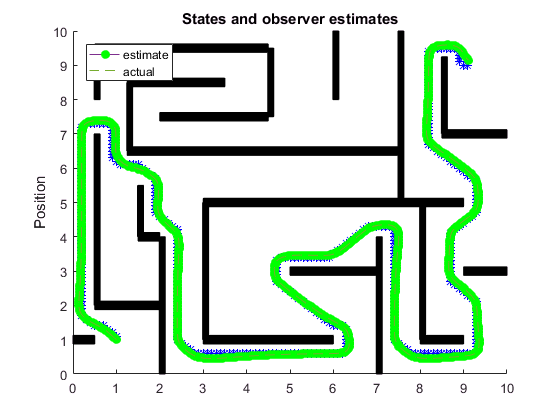

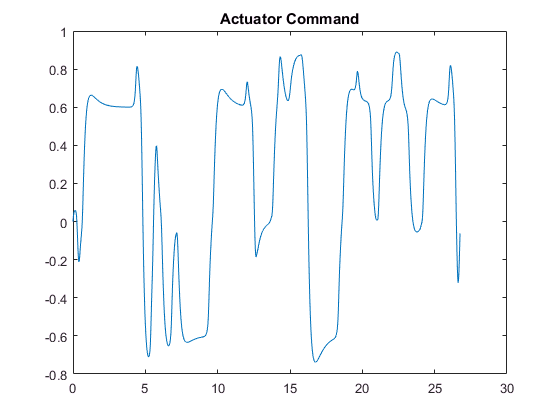

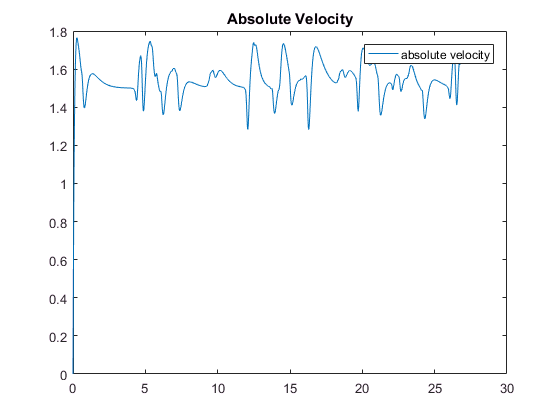

Observe_Control_friction;

## Concluding Remarks

Above we can see that the addition of friction dramatically smooths out both the velocity, and the required actuator signal. We can see that the required signal is both lower in magnitude and much less jittery. As for the velocity, we can see immediately that the maxmium velocity stays below 2. Additionally, our controller is much better at cornering, which is to be expected, considering the frictional force should effectively slow down the point mass around turns. We can also note that while the friction model follows better around corners, the model without friction is much better at reaching set-point on the straight-aways. This is also to be expected as both models asymtoticly approach set-point, however, the friction model has a larger time constant and as a result takes much longer to reach setpoint for small deviations along straight paths. 

## References

1) https://mec560sbu.github.io

2) https://drive.google.com/drive/u/1/folders/0B51BYOSh3EKQMTEzMEdmOXJ1dzg

3) Fowles & Cassiday, *Analytical Mechanics, *Brooks/Cole, Boston, 2005